JOB_ID = 93;
PLT_DATA_ROOT = "/scratch/general/vast/u1424875/neural-feature-identification-pipeline/";
RNG_SEED = 2025;

events_starts = h5read(fullfile(PLT_DATA_ROOT,string(JOB_ID), "events.h5"), '/trial_start_idxs');

Error using h5readc
Unable to open '/scratch/general/vast/u1424875/neural-feature-identification-pipeline/93/events.h5'. File or folder not found.

Error in h5read (line 95)
    [data,var_class] = h5readc(Filename,Dataset,start,count,stride);

events_stops = h5read(fullfile(PLT_DATA_ROOT,string(JOB_ID), "events.h5"), '/trial_stop_idxs');
kinematics_data = h5read(fullfile(PLT_DATA_ROOT,string(JOB_ID), "kinematics.h5"), '/kinematics');
feature_data_nfr = h5read(fullfile(PLT_DATA_ROOT,string(JOB_ID), "/features/NFR.h5"), '/features');
feature_data_sbp = h5read(fullfile(PLT_DATA_ROOT,string(JOB_ID), "/features/SBP-RAW.h5"), '/features');
feature_data_dwt = h5read(fullfile(PLT_DATA_ROOT,string(JOB_ID), "/features/DWT-DB4.h5"), '/features');
feature_data_mav = h5read(fullfile(PLT_DATA_ROOT,string(JOB_ID), "/features/MAV.h5"), '/features');


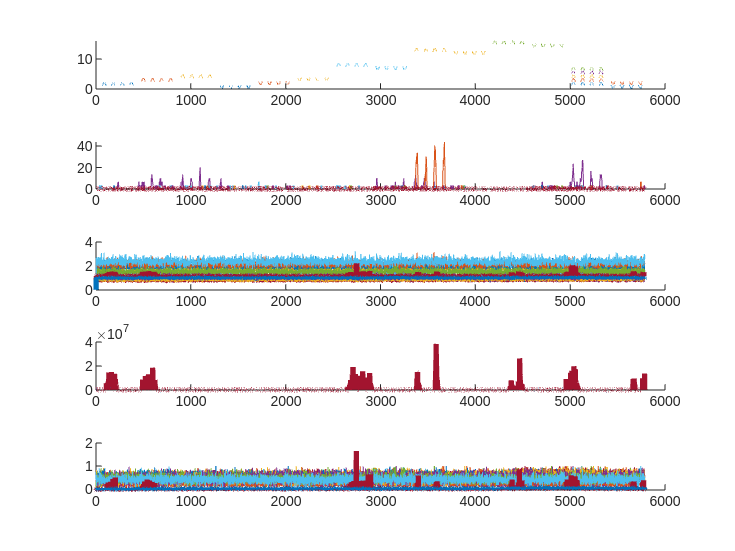

rng(RNG_SEED);
plt_ch_idxs = randi([1,192], 20,1);
fig_h = figure();
tlo = tiledlayout(5,1);
ax1 = nexttile; 
plot(kinematics_data+[1:12]*1.25); box off
ax2 = nexttile;
plot(feature_data_nfr(:, plt_ch_idxs)); box off
hold on; plot(mean(feature_data_nfr, 2), 'LineWidth',3); hold off
hold on; plot(median(feature_data_nfr, 2), 'LineWidth',3); hold off
% yscale log;
ax3 = nexttile;
plot(feature_data_sbp(:, plt_ch_idxs)); box off
hold on; plot(mean(feature_data_sbp, 2), 'LineWidth',3); hold off
hold on; plot(median(feature_data_sbp, 2), 'LineWidth',3); hold off
% yscale log;
ax4 = nexttile;
plot(feature_data_dwt(:, plt_ch_idxs)); box off
hold on; plot(mean(feature_data_dwt, 2), 'LineWidth',3); hold off
hold on; plot(median(feature_data_dwt, 2), 'LineWidth',3); hold off
% yscale log;
ax5 = nexttile;
plot(normalize(feature_data_mav(:, plt_ch_idxs), 1, 'range', [0, 1])); box off
hold on; plot(mean(feature_data_mav, 2), 'LineWidth',3); hold off
hold on; plot(median(feature_data_mav, 2), 'LineWidth',3); hold off
% yscale log
linkaxes([ax1, ax2, ax3, ax4, ax5], 'x')

feature_data = feature_data_nfr;
upper_lim = prctile(feature_data(feature_data>0), 90)

upper_lim = 33.6700

lower_lim = prctile(feature_data(feature_data>0), 0.001)

lower_lim = 3.3670

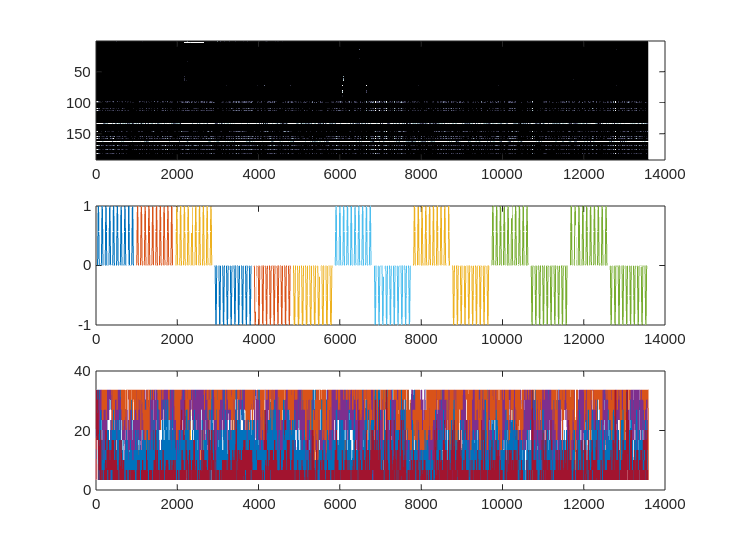

feature_data_clipped = feature_data;
feature_data_clipped(feature_data_clipped > upper_lim) = upper_lim;
feature_data_clipped(feature_data_clipped < lower_lim) = lower_lim;

figure();
tlo = tiledlayout(3,1);
ax1 = nexttile;
imagesc(feature_data_clipped'); colormap("bone")
ax2 = nexttile;
plot(kinematics_data)
ax3 = nexttile;
plot(feature_data_clipped)
linkaxes([ax1, ax2, ax3], 'x')